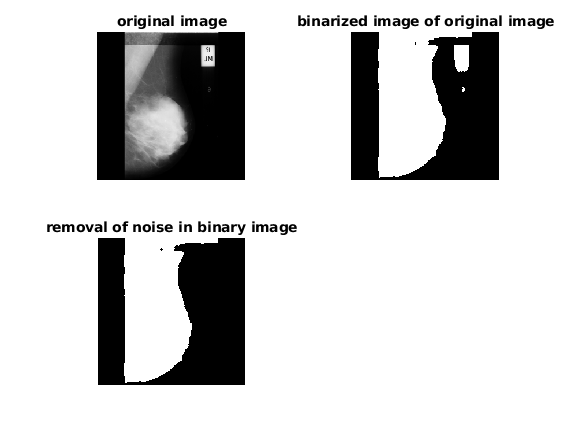

ori_img = imread('mdb002.pgm');
%imshow(ori_img)

ori_img = imresize(ori_img, [256 256]);
%% Convert to gray scale
if size( ori_img , 3) == 3 % RGB image
ori_img = rgb2gray(ori_img);
end
ori_img1 = medfilt2(ori_img);
ori_img1 = adapthisteq(ori_img1,'ClipLimit',0.01,'Distribution','uniform');
imagen1 = im2bw(ori_img1,0.12);
%imshow(imagen1)


%% Compute the area of each component:
CC1 = bwconncomp(imagen1, 4);
S = regionprops(CC1, 'Area');
%% Remove small objects
fig_areas = [S.Area];
[max_area, idx] = max(fig_areas);
extract_fig = false(size(imagen1 ));
extract_fig(CC1.PixelIdxList{idx}) = true;
f1 = extract_fig;
%imshow(f1)


subplot(2,2,1), imshow(ori_img)
title('original image')
subplot(2,2,2), imshow(imagen1)
title('binarized image of original image')
subplot(2,2,3), imshow(f1)
title('removal of noise in binary image')

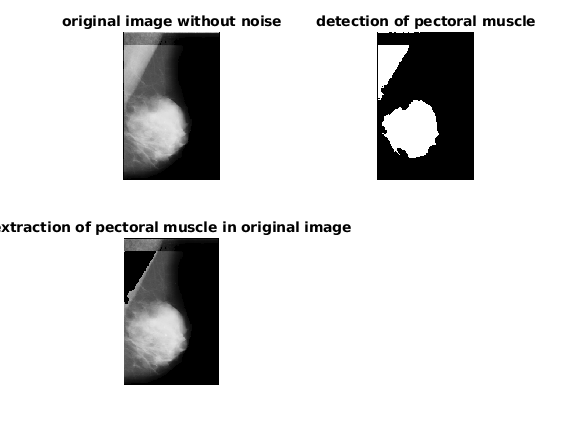


structBoundaries = bwboundaries(f1);
xy=structBoundaries{1}; % Get n by 2 array of x,y coordinates.
x = xy(:, 2); % Columns.
y = xy(:, 1); % Rows.
leftColumn = min(x);
rightColumn = max(x);
topLine = min(y);
bottomLine = max(y);
width = rightColumn - leftColumn + 1;
height = bottomLine - topLine + 1;
croppedImage = imcrop(f1, [leftColumn, topLine, width, height]);
blackMaskedImage = ori_img;
blackMaskedImage(~f1) = 0 ;
croppedImage_ori = imcrop(blackMaskedImage, [leftColumn, topLine, width, height]);
% Display cropped image.
%imshow(croppedImage_ori)


rem_art = croppedImage_ori;
D_filt = medfilt2(rem_art);
D2= imadjust(D_filt, [0.5 0.75], [0.2 0.9] );
D1 = imadjust(D2, [0.5 0.75], [0.2 0.9]);
threshold1 = graythresh(D1);
imagen2 = im2bw(D1, 0.20);
proc_img1 = imagen2;



%% modifying extra components to be present in image
se1 =strel('disk',1);
final1 = imsubtract (croppedImage, proc_img1);
fig_ero = bwmorph(final1, 'close');
final_fill = imfill(fig_ero, 'holes');
blackMaskedImage1 = rem_art;
blackMaskedImage1(~final_fill) = 0 ;
% Display cropped image.

figure
subplot(2,2,1), imshow(croppedImage_ori)
title('original image without noise')
subplot(2,2,2), imshow(proc_img1)
title('detection of pectoral muscle')
subplot(2,2,3), imshow(blackMaskedImage1)
title('extraction of pectoral muscle in original image')

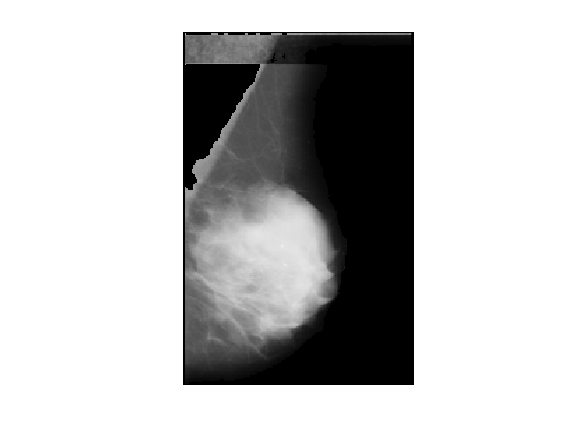

figure
imshow(blackMaskedImage1)

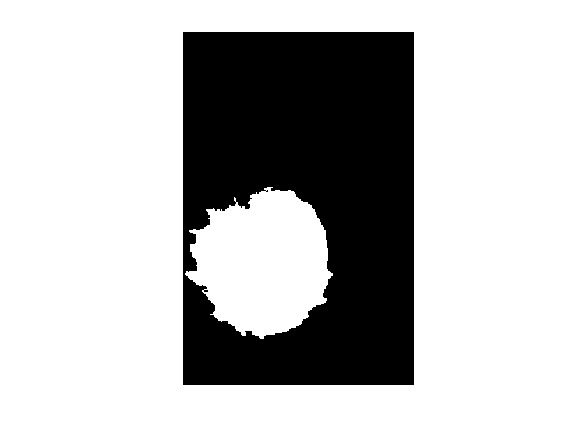


%Roi segmentation
%I = imread('pect.pgm');

gmag = imgradient(blackMaskedImage1);
%imshow(gmag,[])
%title('Gradient Magnitude')
se = strel('disk',40);
Io = imopen(blackMaskedImage1,se);
%imshow(Io)
%title('Opening')
Ie = imerode(blackMaskedImage1,se);
Iobr = imreconstruct(Ie,blackMaskedImage1);
%imshow(Iobr)
%title('Opening-by-Reconstruction')
Ioc = imclose(Io,se);
%imshow(Ioc)
%title('Opening-Closing')
Iobrd = imdilate(Iobr,se);
Iobrcbr = imreconstruct(imcomplement(Iobrd),imcomplement(Iobr));
Iobrcbr = imcomplement(Iobrcbr);
%imshow(Iobrcbr)
%title('Opening-Closing by Reconstruction')
fgm = imregionalmax(Iobrcbr);

maskedImage = blackMaskedImage1; % Initialize
maskedImage(~fgm) = 0; % Mask

figure
imshow(fgm)

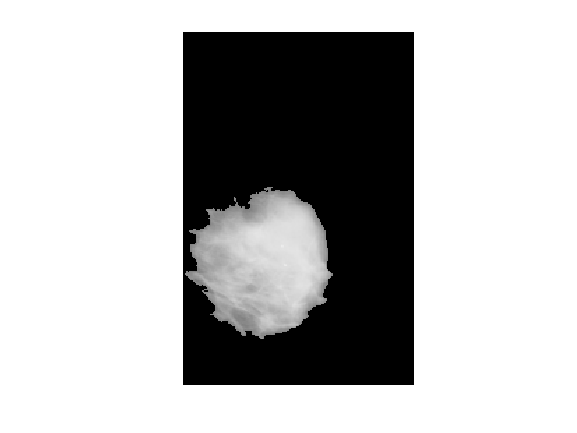

imshow(maskedImage)